# Sample 12-6

## 画像復元

交互方向乗数法 (ADMM)

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Image restoration

Alternating Direction Method of Multipliers (ADMM)

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

clear 
close all

### パラメータ設定

(Parameter settings)

lambda = 10^-2;
rho = 1;
niters = 100;

## 画像の読込

(Read image)

T = 0.3*im2double(imread('text.png'));
B = 0.7*imresize(checkerboard,size(T));

## 観測画像

(Observation image)

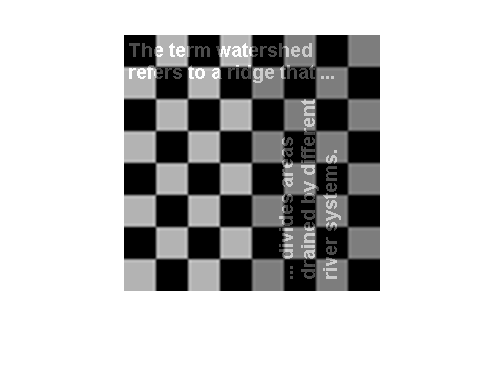

M = T + B;
figure(1)
imshow(M)

imwrite(M,'admmm.png')

### 交互方向乗数法

(Alternating direction method of multipliers)

#### 問題設定 (Problem settings):

        
$$\min_{\mathbf{u},\mathbf{y}} f(\mathbf{u})+g(\mathbf{y}),\quad  \mathbf{y}=\mathbf{Gu}$$


- $f(\cdot),g(\cdot)$: Convex functions

- $\mathbf{G}$: Full rank matrix

#### アルゴリズム (Algorithm):

- Initialization: $\mathbf{d}^{(0)}$,$\mathbf{y}^{(0)}$, $t\leftarrow 0$

- 
$$\mathbf{u}^{(t+1)} \leftarrow \arg \min _{\mathbf{x}} f(\mathbf{x})+\frac{\rho}{2}\left\|\mathbf{y}^{(t)}-\mathbf{G} \mathbf{x}-\mathbf{d}^{(t)}\right\|_{2}^{2}$$


- 
$$\mathbf{y}^{(t+1)} \leftarrow \mathrm{prox}_{\rho^{-1} g}\left(\mathbf{G} \mathbf{u}^{(t+1)}+\mathbf{d}^{(t)}\right)$$


- 
$$\mathbf{d}^{(t+1)} \leftarrow \mathbf{d}^{(t)}+\mathbf{G} \mathbf{u}^{(t+1)}-\mathbf{y}^{(t+1)}$$


- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

ただし，(where) 

        
$$\rho>0$$


【Example】Robust principal component analysis (Robust PCA)

        
$$\mathbf{M}=\mathbf{L}+\mathbf{S}$$


問題設定(Problem settings)

        
$$\min _{\mathbf{L}, \mathbf{S}}\|\mathbf{L}\|_{*}+\lambda\|\mathbf{S}\|_{1},\ \quad \mathrm{s.t.}\ \mathbf{M}=\mathbf{L}+\mathbf{S}$$


            
$$\Updownarrow$$


        
$$\min_{\mathbf{u},\mathbf{y}} f(\mathbf{u})+g(\mathbf{y}),\quad  \mathbf{y}=\mathbf{Gu}$$


ただし，(where)

- $\|\cdot\|_{*}$: Nuclear norm (sum of singular values $\{\sigma_k\}$)

- $\|\cdot\|_{1}$: $\ell_1$-norm as a vector (sum of absolute of elements)

- 
$$f(\mathbf{u})=0$$


- 
$$g(\mathbf{y})=\|\mathbf{\ell}\|_\ast+\|\mathbf{s}\|_1+\imath_{\{\mathbf{m}\}}(\mathbf{\ell}+\mathbf{s})$$


- $\mathbf{y}=\left(\begin{array}{c}\mathbf{\ell} \\ \mathbf{s} \\ \mathbf{\ell}+\mathbf{s} \end{array}\right)$,$\mathbf{u}=\left(\begin{array}{c}\mathbf{\ell} \\ \mathbf{s}  \end{array}\right)$, $\mathbf{G}=\left(\begin{array}{cc} \mathbf{I} & \mathbf{O} \\ \mathbf{O} & \mathbf{I} \\ \mathbf{I} & \mathbf{I} \end{array}\right)$

- $\mathbf{\ell}:=\mathrm{vec}(\mathbf{L})$, $\mathbf{s}:=\mathrm{vec}(\mathbf{S})$

アルゴリズム (Algorithm)

% Step1: Initialization
imgY1 = M;
imgY2 = zeros(size(M),'like',M);
imgY3 = M;
imgD1 = zeros(size(M),'like',M);
imgD2 = zeros(size(M),'like',M);
imgD3 = zeros(size(M),'like',M);

for idx=1:niters   
    % Set state variables
    Y1 = imgY1;
    Y2 = imgY2;
    Y3 = imgY3;
    D1 = imgD1;
    D2 = imgD2;
    D3 = imgD3;
    
    % Step 2: Update L S
    L = (2*(Y1-D1) - (Y2-D2) + (Y3-D3))/3;
    S = (Y1-D1) + (Y3-D3) - 2*L;
    
    % Step 3-1: Update Y1
    Y1 = proxnuclearnorm(L + D1, 1/rho);
    % Step 3-2: Update Y2
    Y2 = softthresholding(S + D2, lambda/rho);
    % Step 3-3: Update Y3
    Y3 = M;
    
    % Step 4: Update dual variables
    D1 = D1 + L - Y1;
    D2 = D2 + S - Y2;
    D3 = D3 + L + S - Y3;
    
    % Update state variables
    imgY1 = Y1;
    imgY2 = Y2;
    imgY3 = Y3;
    imgD1 = D1;
    imgD2 = D2;
    imgD3 = D3;
end

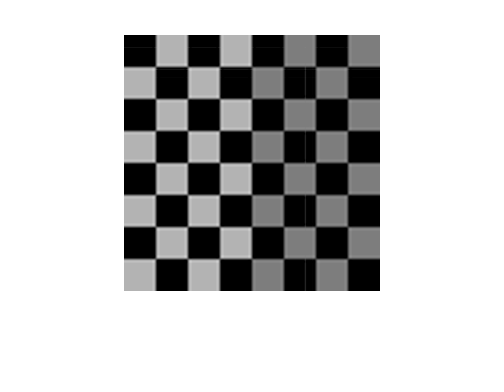

figure(2)
imshow(L)

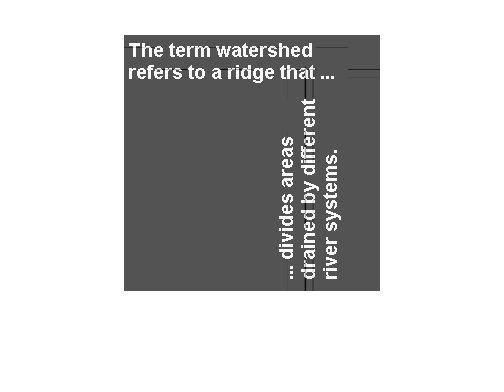

figure(3)
imshow(S,[])

function y = softthresholding(x,lambda)
    y = sign(x).*max(abs(x)-lambda,0);
end

function y = proxnuclearnorm(x,lambda)
    [U,S,V] = svd(x,'econ');
    T = softthresholding(S,lambda);
    S(1:size(T,1),1:size(T,2)) = T;
    y = U*S*V';
end

© Copyright, Shogo MURAMATSU, All rights reserved.